clear;
clc;
close all;

% setup
nx = 100;
dx = 2*pi/nx;
X = dx*(1:nx);

f = @(u) 0.5*u.^2; % flux function

u0 = (sin(X/2)).^2;
t0 = 0;
tf = 5;
CFL = 0.5;

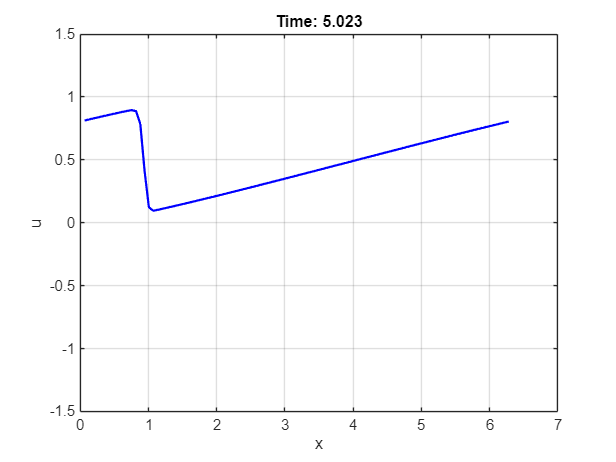

% algorithm
u = u0;
t = t0;
U = u;
T = t;
while t < tf
    dt = CFL*dx/max(abs(u)); % compute dt (dynamic)

    F = zeros(size(u)); % cell interface flux

    % % need to handle i==1 differently
    % uL = u(end);
    % uR = u(1);
    % % solve riemann problem
    % if uL > uR
    %     F(1) = f(uL);
    % else
    %     F(1) = f(uR);
    % end
    % 
    % for i = 1:nx
    %     uL = u(i-1);
    %     uR = u(i);
    %     % solve riemann problem
    %     if uL > uR
    %         F(i) = uL;
    %     else
    %         F(i) = uR;
    %     end
    % end
    for i = 1:nx
        uL = u(i);
        uR = u(mod(i,nx)+1);
        if uL > uR
            % F(i) = f(uL);
            F(i) = max(f(uL),f(uR)); % need to take max/min????
        else
            % F(i) = f(uR);
            F(i) = min(f(uL),f(uR));
        end
    end
    
    % update using godunov
    u = u - dt/dx*(F-[F(end) F(1:end-1)]);
    t = t + dt;
    U = [U; u];
    T = [T; t];

    % plot
    plot(X, u, 'b-', 'LineWidth', 1.5);
    title(sprintf('Time: %.3f', t));
    xlabel('x');
    ylabel('u');
    ylim([-1.5, 1.5]);
    grid on;
    pause(0.01);
end